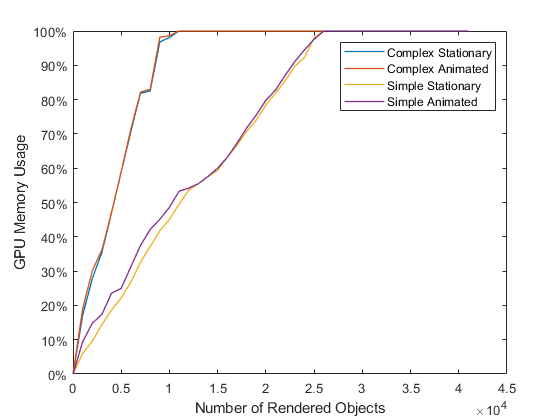

%GPU Usage Complex vs Simple
figure
plot(ObjectNum, GPU_sat_Station, 'LineWidth', 1)
hold on
plot(ObjectNum, GPU_SAT_ANIM, 'LineWidth', 1)
hold on
plot(ObjectNum, GPU_DISH_STATION, 'LineWidth', 1)
hold on
plot(ObjectNum, GPU_DISH_ANIM, 'LineWidth', 1)
yticklabels({'0%','10%','20%','30%','40%','50%','60%','70%','80%','90%','100%'})
xlabel ('Number of Rendered Objects')
ylabel ('GPU Memory Usage')
legend('Complex Stationary','Complex Animated', 'Simple Stationary', 'Simple Animated')

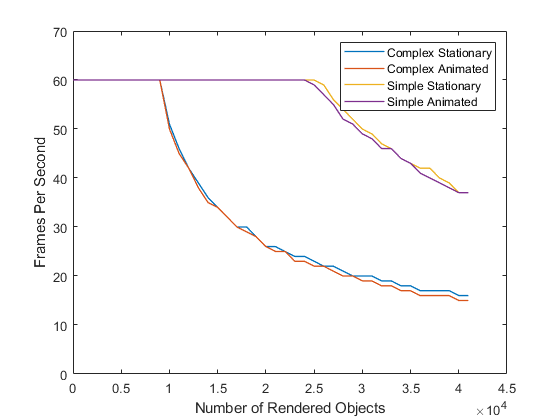


%FPS Usage Complex vs Simple
figure
plot(ObjectNum, FPS_SAT_STATION, 'LineWidth', 1)
hold on
plot(ObjectNum, FPS_SAT_ANIM, 'LineWidth', 1)
hold on
plot(ObjectNum, FPS_DISH_STAT, 'LineWidth', 1)
hold on
plot(ObjectNum, FPS_DISH_ANIM, 'LineWidth', 1)
ylim ([0,70])
xlabel ('Number of Rendered Objects')
ylabel ('Frames Per Second')
legend('Complex Stationary','Complex Animated', 'Simple Stationary', 'Simple Animated')


%Draw Calls
instancecalls = ones(42,1)

instancecalls =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


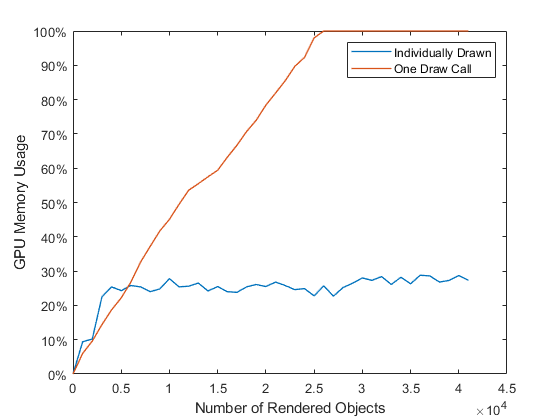

figure 
plot(ObjectNum, GPU_DrawCalls, 'LineWidth', 1)
hold on
plot( ObjectNum, GPU_DISH_STATION, 'LineWidth', 1)
hold on
yticklabels({'0%','10%','20%','30%','40%','50%','60%','70%','80%','90%','100%'})
xlabel ('Number of Rendered Objects')
ylabel ('GPU Memory Usage')
legend('Individually Drawn','One Draw Call')

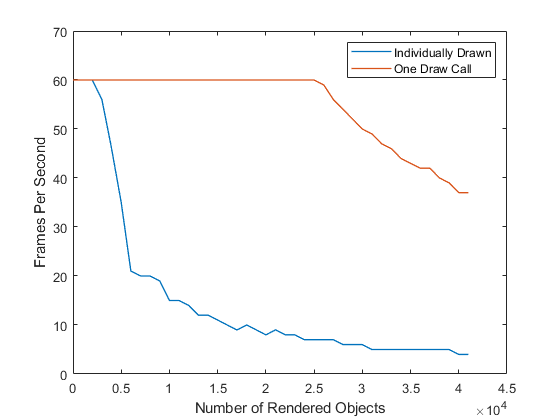


figure 
plot(ObjectNum, FPS_DrawCalls, 'LineWidth', 1)
hold on
plot( ObjectNum, FPS_DISH_STAT, 'LineWidth', 1)
hold on
ylim ([0,70])
xlabel ('Number of Rendered Objects')
ylabel ('Frames Per Second')
legend('Individually Drawn','One Draw Call')

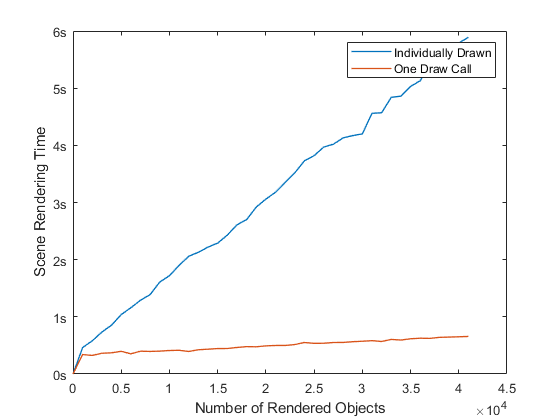


figure 
plot(ObjectNum, RenderTime_DrawCalls, 'LineWidth', 1)
hold on
plot( ObjectNum, RenderTime_Dish, 'LineWidth', 1)
hold on
xlabel ('Number of Rendered Objects')
ylabel ('Scene Rendering Time')
yticklabels({'0s','1s','2s','3s','4s','5s','6s'})
legend('Individually Drawn','One Draw Call')